% generate some fake data

x = [2.5 2.8 3.4 2 1.2 2.1 1.8 2.8 1.1 2.2 3.2 0.61 3 0.53 2 0.45 2 ...
1 -0.53 1.2 2.2 2.5 1.9 1.9 2.8 2.8 1.3 3.1 2.7 2.3 0.47 2.1 1.5 3.8 ...
3 2.8 0.97 2.5 2.3 3.9 0.54 3.6 2.3 2.7 4.4 2.7 0.44 2.1 1.7 2.1].^2;


y = [5.9 6.4 3.7 3.1 5.1 3.6 6.2 5.1 3 4.7 6 1.2 6.1 -0.51 4.4 3 ...
5.1 2.2 0.14 3.2 7.2 7.4 4 4.5 5.3 2 4.9 3 4.6 3.9 3.5 4.2 3.6 5.4 ...
4.5 6.1 2.6 4.9 3.5 4.8 1 6.8 4.2 3.7 7.5 1.7 2.8 1.8 3.6 4.3].^2;
%

% compute the actual correlation value observed

actualcorr = corr(x(:),y(:));

% draw bootstrap samples and compute correlation values

results = zeros(1,10000);

for num=1:10000
    
    % vector of indices (each element is a random integer between
    % 1 and n where n is the number of data points)
    
    % an array of indexes to take for each bootstrap sample
    ix = ceil(length(x)* rand(1, length(x)));
    
    % Randomly chosen elements from the original sample
    % Use inverted matrix (aka matrix-vector) to fit corr'-functon
    % requirements
    x_i = x(ix)';
    y_i = y(ix)';
    
    % Correlation on num-th step
    corr_num = corr(x_i,y_i);
    
    results(num) = corr_num;
    
end

% Or could use MATLAB's bootstrp.m function to achieve the same results:
%   results = bootstrp(10000, @(x0,y0) corr(x0,y0),x',y');
%

ptiles = prctile(results, [2.5 97.5]);

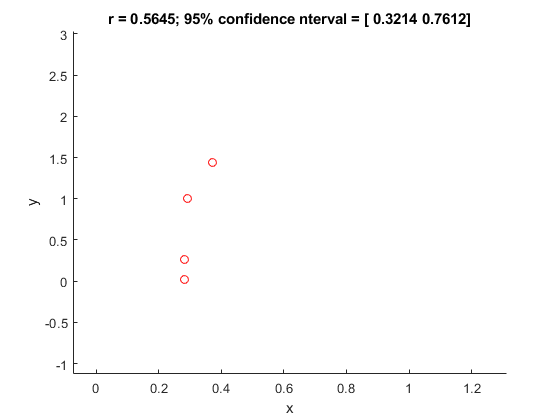

% visualize

figure; hold on;
scatter(x,y,'ro');

xlabel('x');
ylabel('y');

title(sprintf('r = %.4f; 95%% confidence nterval = [ %.4f %.4f]', actualcorr, ptiles(1),ptiles(2)));